# 第五章 数字图像与视频压缩编码原理

## 基于DCT的图像编码

【例5-6】输入一幅大小为512x512像素、灰度级为256的标准图像Lena，将其分割成4096个8x8像素子图像，对每个图像进行DCT（Discrete cosine transform），这样每个子图像就有64个DCT变换系数，舍去其中32个较小的变换系数，保留32个较大的变换系数，实现2：1的数据压缩，然后进行逆变换。

%设置压缩比cr
cr=0.5;%0.5为2:1压缩比，0.125为8:1压缩比
I=imread('lena512.bmp');%图像的大小为512x512像素
I1=double(I)/255;%图像为256级灰度图像，对图像进行归一化操作
%获取DCT变换矩阵
t=dctmtx(8);
%对图像分为64*64个8*8的子块，并对各个子块进行DCT变换
fun1=@(block_struct)(t*block_struct.data*t');
dctcoe=blockproc(I1,[8 8],fun1);

%舍去不重要的系数
coevar=im2col(dctcoe,[8 8],'distinct');
[y ,ind]=sort(coevar);
[~,n]=size(coevar);
snum=64-64*cr;
coe=coevar;
for i=1:n
    %将每个子块中最小的snum个变换系数设置为0
    coe(ind(1:snum),i)=0;
end
b2=col2im(coe,[8 8],[512 512],'distinct');

%对截取后的DCT变换系数经行DCT逆变换
fun2=@(block_struct)(t'*block_struct.data*t);
I2=blockproc(b2,[8 8],fun2);

变换效果如图：

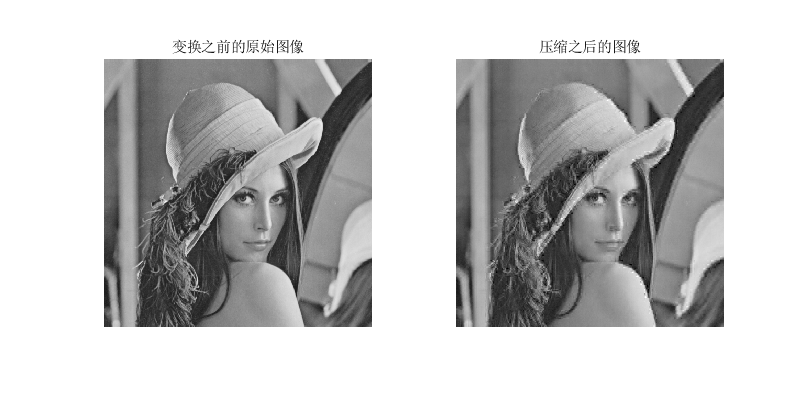

figure('Position',[0,0,800,400])
subplot(1,2,1)
imshow(I1);title('变换之前的原始图像')
subplot(1,2,2)
imshow(I2);title('压缩之后的图像')

计算均方根误差erms

e=double(I1)-double(I2);
[m,n]=size(e);
erms=sqrt(sum(e(:).^2))/(m*n);
fprintf("cr=%g, 压缩比为%g:1时, erms=%f",cr,1/cr,erms)

cr=0.5, 压缩比为2:1时, erms=0.000062

## 附

### 附1、关于lena图像的说明

matlab自带的图像处理工具箱中移除了lena的标准测试图片（可能时版权原因），然而在网络中可以比较容易地找到相关的图片，如[Standard test images - Lena/Lenna (rice.edu)](https://www.ece.rice.edu/~wakin/images/)